**Introduction to Simulink**

*This is a live script file. To run each section press ctrl+Enter / cmd+Enter.*

We will consider the two tanks system, as seen in class.

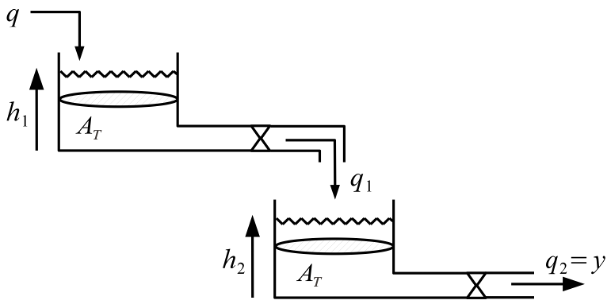

Its dynamics are given by:


$$\left\lbrack \begin{array}{c}
{\dot{x} }_1 \\
{\dot{x} }_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-3 & 0\\
3 & 5
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack u$$


and its output equation is


$$y=\left\lbrack \begin{array}{cc}
0 & 5
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$$


The model can be found in the `tanks.slx` file, where we also set the initial conditions $h_1 \left(0\right)=h_{2\;} \left(0\right)=0\ldotp 1\;\mathrm{m}$.

Let define now the input signals. For that purpose, we add a step and sinusoidal block in the Simulink model and define here their parameters.

% Sinusoidal
a = 0.2;        % [m^3/s]
omega = 5;      % [rad/s]
% Step
qbar = 1.5;     % [m^3/s]
t_step = 0;

We also define the input in an alternative way. We construct it in Matlab and pass the sequence to Simulink using the simin block.

% Simin signal
simin.time = [0:0.1:10]';
simin.signals.values = qbar + a*sin(omega*simin.time);

By clicking on run, or running the following lines, we simulate the system. The output can be observed by double click on the scope block. Alternatively, one can export the signals to Matlab and then plot them, as done in next section.

*Note that the plot and displayed text appears in this live-script. In may appear in the right column on below the section of the code that generated it, depending on your settings.*

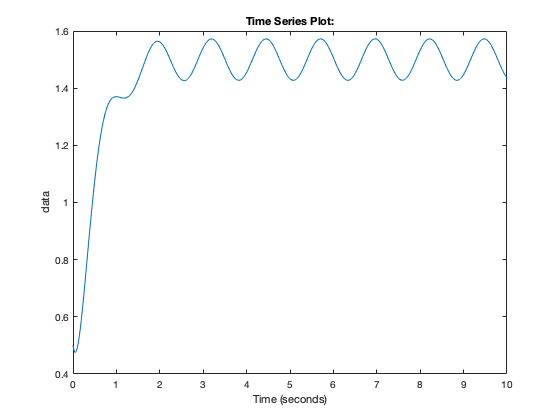

% Simulate the system
model = sim("tanks");
plot(model.simout)

fprintf("The input signal consists of a step of " + ...
    "amplitude %.1f, \nplus a sinusoidal of amplitude " + ...
    "%.1f and frequency %.1f rad/s.", qbar, a, omega)

The input signal consists of a step of amplitude 1.5, 
plus a sinusoidal of amplitude 0.2 and frequency 5.0 rad/s.

**MIMO two-tank system**

We now consider a modified version where a new tube is added allowing the system to have a second input. Moreover, we can measure the flow of the liquid exiting the first tank.

Then, the new model is:


$$\left\lbrack \begin{array}{c}
{\dot{x} }_1 \\
{\dot{x} }_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-3 & 0\\
3 & 5
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack u$$



$$y=\left\lbrack \begin{array}{cc}
3 & 0\\
0 & 5
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$$


Its implementation can be found in the `tanks2.slx`. We now define the parameters of the input signals in order to run the corresponding Simulink model.

%% Double tank system with two inputs and two outputs
qbar1 = 1.5;    % [m^3/s]
qbar2 = 0.5;    % [m^3/s]
a = 0.2;        % [m^3/s]
omega1 = 8;     % [rad/s]
omega2 = 5;     % [rad/s]
simin2.time = [0:0.1:10]';
simin2.signals.values = horzcat(qbar1 + a*sin(omega1*simin2.time),...
    qbar2 + a*sin(omega2*simin2.time));

We can either press the run button on Simulink and see the results on the scope block, or use a simout block to export to the data to Matlab. The latter is implemented in the following section.

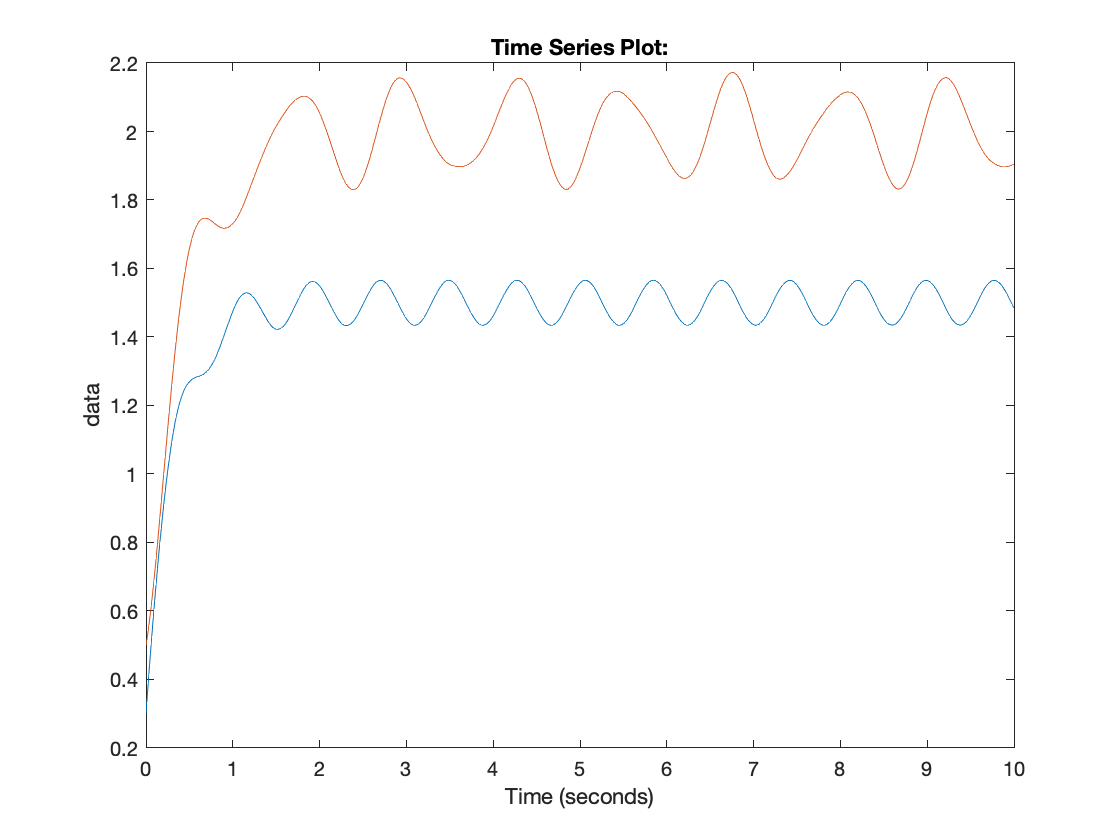

% Simulate the system
model = sim("tanks2");
plot(model.simout2)

**Exercise: three tanks system**

The new tank (T3) has a model given by


$${\dot{x} }_3 =-\frac{2}{3}x_3 +5u_3$$



$$y_3 =2x_3$$


We define this new system as a state-space model in Simulink and we connect it with the existing two-tanks model by connecting the output of T3 to the first input of the two-tanks system. See `tanks3.slx` file.

 As indicated by the exercise, we consider pulse signals plus an offset (modeled with a step) as input signals.

To simulate the system one can press on the run button or alternatively run the next section.

% Simulate the three-tanks system
model = sim("tanks3");

**Non-linear systems in Simulink**

The file `pendulum.slx` contains two equivalent models to simulate the pendulum model given by


$$\theta^˙ =\omega \;$$



$$\omega^˙ =-b\omega -g\;\sin \;\theta +u$$


where the parameters $b$ and $g$ are defined by:

g = 9.8; b = 1;

Note that for the second model in `pendulum.slx,` we use an 'Interpreted MATLAB function'. This function is defined in a separate file, `pendulum_func.m`, but it could also be added in the live-script by defining a function section.

Let's run the pendulum system.

% Simulate the pendulum system
model = sim("pendulum");

The state dynamics can be seen on the scope blocks.